# Práctica 6: Firmas y Certificados Digitales

**FUNCIONES MATLAB EMPLEADAS**

- **sym() **declaración de variables simbólicas.

- **gcd() **m.c.d y coeficientes de Bézout.

- **lcm() **minimo común múltiplo.

- **quorem() **división euclidea.

- **powermod() **potencia con clases de congruencia. Permite calcular la clase inversa.

- **isprime()** devuelve 1/0  si un número es o no primo.

- **nextprime() **siguiente prime a un número dado.

- **strcat() **concatena horizontalmente las cadenas de texto proporcionadas como entrada.

Las firmas y certificados digitales son una aplicación de la criptografía en clave pública. La firma digital tiene la misma finalidad que la tradicional firma “en papel”, pero con documentos digitales. Y a diferencia de aquella, se pretende que sea **auténtica **e **infalsificable**, de modo que sólo quién manifiesta haber firmado un documento digital haya podido hacerlo; y también **inalterable**, para que después que un documento haya sido firmado, no sea posible alterarlo sin que la firma siga siendo válida. Un certificado digital proporciona a un persona (o entidad) una identidad en internet. También debe ser auténtico e infalsificable y, además, servir para que una persona se identifique remotamente ante otra de manera inequívoca. 				

En esta práctica vamos vamos a crear firmas y certificados digitales con MATLAB a partir del criptosistema RSA, estudiado en la práctica anterior. 

**Borrón y cuenta nueva!!**

clc, clear, close all

## 1. Firma digital

La obtención de una firma digital a partir de un criptosistema de clave pública es bastante simple: se obtiene primero un **resumen** del documento digital que se quiere firmar y se cifra con la clave **privada**. Este cifrado es precisamente la firma digital del documento. Es infalsificable porque sólo el conocedor de la clave privada ha podido generar la firma. Para comprobar la autenticidad de la misma, se descifra con la clave pública y se comprueba si coincide con el resumen del documento. La inalterabilidad de la firma nos la proporciona el resumen del documento, ya que se obtiene con una función hash. 

### 1.1. Funciones hash

Una función hash comprime una secuencia de bits, de cualquier longitud, en otra de unos pocos bits de modo que, si cambiamos un sólo bit en la secuencia inicial, el resultado es totalmente diferente. Con cierta formalidad: una función $h$, que a cada secuencia finita de bits $s$ le hace corresponder otra $h(s)$ de un número fijo de bits, se dice una función hash si es prácticamente imposible encontrar dos secuencias distintas $s$ y $t$ tales que $h(s) = h(t)$. La imagen $h(s)$ es el resumen de la secuencia $s$.

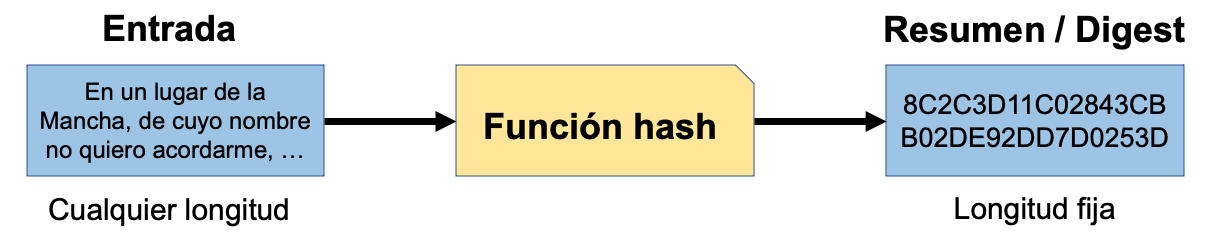

Aquí vamos a emplear la función hash MD5 que viene implementada en MATLAB con el nombre `Simulink.getFileChecksum()`. Produce resumenes de 128 bits de un archivo cuyo nombre se pasa como parámetro. Por ejemplo, si queremos obtener el valor de la función hash MD5 aplicada al archivo PDF 'principiamathematica.pdf' que contiene la portada del volumen 1 del famoso libro **Principia mathematica**, escrito por Bertrand Russell y Alfred North Whitehead, usaremos

Simulink.getFileChecksum('principiamathematica.pdf')

ans = '3D372500C87B4816C28584A54788634C'

Observamos que el resultado es una cadena de 32 caracteres hexadecimales (de 4 bits): los 128 bits que decíamos. 

Nota: Hoy en día, la función MD5 ha quedado obsoleta y en su lugar se utilizan las funciones de la familia SHA (Secure Hash Algorithm), que producen resúmenes con más bits. 

Se ha implementado la función `MD5` que se proporciona como un fichero auxiliar en la práctica, la cual permite calcular la función hash MD5 de un fichero proporcionado como entrada. Posteriormente, en el apartado 3 utilizaremos esta misma función para obtener el hash de una cadena de texto. Por lo tanto, para obtener el valor del hash MD5 del fichero 'principiamathematica.pdf' podrémos usar:

MD5('principiamathematica.pdf')

ans = '3D372500C87B4816C28584A54788634C'

### 1.2. Firmas RSA

Consideramos una clave RSA de por lo menos 200 bits: ($n$, $e$, $d$), siendo siendo $n$ el módulo, $e$ el exponente y $d$ la clave privada. Los resúmenes producidos por la anterior función MD5 podemos contemplarlos como enteros representados en base 16 (hexadecimal). Sea $m$ el resumen generado al aplicar la función MD5 a un fichero concreto. Antes de cifrar $m$ con la clave privada, lo vamos a “enmascarar” de la siguiente manera: Generamos un entero aleatorio **impar** $g$ de 64 bits. Como es impar, tiene inverso módulo $2^{128}$. Sea $g^{-1}$ este inverso, calculado `powermod(g, -1, sym(2)^128)`. Calculamos $h = g^{-1}\cdot m$ mod $2^{128}$ y construimos $M = g \cdot 2^{128} + h$. (Notamos que $M$ tiene 192 bits y, por tanto, es menor que el módulo $n$). Calculamos 					

     
$$f = M^d \pmod{n}$$


y lo representamos en base 16. Finalmente, la cadena hexadecimal obtenida es la firma digital. 			

Nota: La función hash MD5 empleada devuelve una cadena de caracteres hexadecimales, no obstante, para operar en MATLAB se deben utilizar enteros simbólicos. Para convertir esta cadena hexadecimal de caracteres en enteros simbólicos se puede emplear la función de MATLAB `sym()`, que fue vista en la práctica anterior, poniéndo el string ‘0x’ delante de la cadena a convertir. Recíprocamente, puede obtenerse la representacion hexadecimal de cualquier entero con `dec2hex()`.

Observaciones:										

- La razón de enmascarar $m$ es que si ciframos $m$ directamente entonces de la ecuación $f = m^d \pmod{n}$ podría recuperarse la clave privada $d$ mediante el cálculo de logaritmos discretos, ya que $m$, $f$ y $n$ son públicos.

- Es importante notar que la inclusión del entero aleatorio $g$ hace que la obtención de la firma digital no sea un proceso determinista: cada vez que se firme un mismo documento se obtendrán firmas diferentes. Esto no importa: lo importante es que sólo el conocedor de la clave privada $d$ puede generarlas.

- En la actualidad, se utilizan claves RSA de 2048 bits. Y el proceso de enmascaramiento del resumen es más complejo. 						

#### Ejercicio 1:

Implementar en MATLAB una función, `DigitalSignature()`, que admita como parámetros el nombre de un archivo, el módulo de una clave RSA y su clave privada, y devuelva la firma digital del archivo conforme a la construcción anterior. Se proporciona como ayuda la función `RandomOdd()` que genera un número simbólico aleatorio impar de 64 bits y que puede ser usada para generar $g$. 

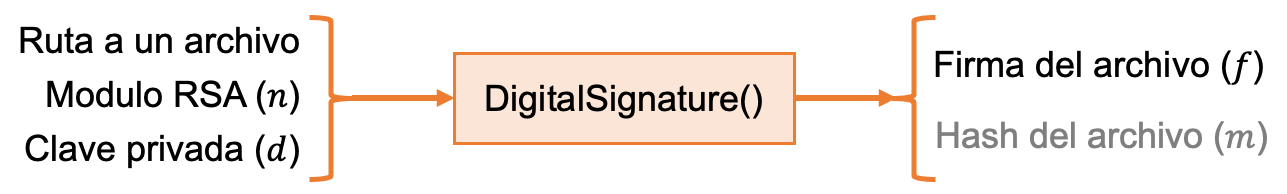

#### Ejercicio 2:

En el archivo `data.mat` figura la clave RSA `keyAuto `de una determinada autoridad de certificación. Es una estructura con tres **enteros simbólicos**: `modulus`, `exponent` y `private` que contienen, respectivamente, el módulo, la clave pública y la clave privada. Con esta clave `keyAuto`, se pide firmar el archivo `principiamathematica.pdf` que se proporciona. Completa el siguiente fragmento de código para realizar la firma del fichero y mostrar dicha firma por pantalla del modo habitual en este contexto: *como cadena de caracteres hexadecimales*. 

Nota: Para cargar el archivo de datos `data.mat`, se puede utilizar el comando `load('data.mat')`. 

## Completar con el código correspondiente

load('data.mat');

[hash firma] = DigitalSignature('principiamathematica.pdf',keyAuto.modulus,keyAuto.private)

hash = '3D372500C87B4816C28584A54788634C'

firma = '9771C8B88954B03F39538395A43C551F2F699C060BA7A0B08426AF35BEE362DC'

## 2. Verificación de una firma digital

Elevando $f$ al exponente $e$ (clave pública) módulo $n$ recuperamos $M$. Y con $M$, obtenemos $m$ de la siguiente manera: 


$$M = f^e \pmod{n}$$


M = powermod(f,e,n);

Recordad que $M = g \cdot 2^{128} + h$, por lo tanto, primero dividimos $M$ entre $2^{128}$. De esta manera, el cociente de la división será $g$ y el resto $h$. En MATLAB se puede utilizar la función `quorem(A, B)`, la cual devuelve el cociente y el resto de dividir A entre B. 

Recordad también que $h = g^{-1} \cdot m \pmod{2^{128}}$, por lo tanto, múltiplicando ambos lados de la expresión por $g$, tenemos: 

     $g \cdot h = g \cdot g^{-1} \cdot m \pmod{2^{128}} \longrightarrow g \cdot h = m \pmod{2^{128}}$. 

De esta manera, queda que $m = (g \cdot h) \pmod{2^{128}}$. Sólo resta comprobar si $m$ es el entero que se corresponde con el resumen del documento firmado. En tal caso, la firma es válida. En otro caso, no lo es. 

#### Ejercicio 3:

Implementar en MATLAB una función, `ValidateSignature()`, que admita como parámetros el nombre de un archivo, una cadena hexadecimal (la fima), el modulo de una clave RSA y su exponente; y devuelva tres datos: el primero, una variable booleana que indique si la firma es válida; el segundo, el valor $m$ oculto en la firma, en hexadecimal; y el tercero el hash del archivo. 

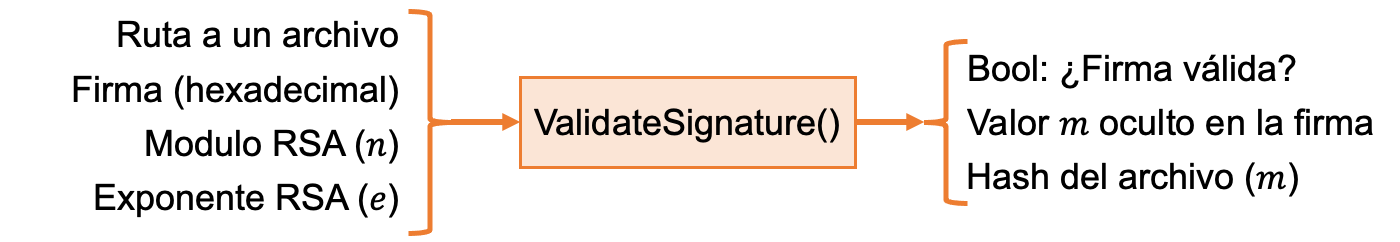

A continuación, verifica la firma del archivo `principiamathematica.pdf` realizada en el ejercicio 2.

%% Completar con el código correspondiente
[valido m hash] = ValidateSignature('principiamathematica.pdf',firma,keyAuto.modulus,keyAuto.exponent)

valido = logical
   1


m = '3D372500C87B4816C28584A54788634C'

hash = '3D372500C87B4816C28584A54788634C'

¿Qué pasa si verificamos la firma del archivo anterior pero utiliamos una copia de `principiamathematica.pdf` modificada (u otro archivo completamente diferente)?

%% Completar con el código correspondiente
[valido m hash] = ValidateSignature('principiamathematic.pdf',firma,keyAuto.modulus,keyAuto.exponent)

valido = logical
   0


m = '3D372500C87B4816C28584A54788634C'

hash = '2B8797E4EAA2A684075F0D30EA1FCCC4'

#### Ejercicio 4:

El archivo `data.mat` contiene el array: `Signatures_principiamathematica` con 5 firmas digitales del archivo `principiamathematica.pdf`. Algunas de estas firmas son legítimas mientras que otras son suplantaciones, no obstante, usando la clave pública de la autoridad `keyAuto` podemos identificar cuales son las firmas legítimas del fichero. ¿Cuáles de esas 5 firmas han sido obtenidas con la clave `keyAuto`? Presentar la respuesta en forma de tabla donde se vea si `Signatures_principiamathematica{i}` es auténtica, el correspondiente valor $m$, en hexadecimal, y el hash del archivo. 

%% Completar con el código correspondiente
for i = 1:length(Signatures_principiamathematica)
    [valido m hash] = ValidateSignature('principiamathematic.pdf',Signatures_principiamathematica(i),keyAuto.modulus,keyAuto.exponent)
end

valido = logical
   0


m = 'E860F18E0F5C130161174CED746AD031'

hash = '2B8797E4EAA2A684075F0D30EA1FCCC4'

valido = logical
   0


m = '3D372500C87B4816C28584A54788634C'

hash = '2B8797E4EAA2A684075F0D30EA1FCCC4'

valido = logical
   0


m = '973147E4468B56DFF071B9B42DA6D2B8'

hash = '2B8797E4EAA2A684075F0D30EA1FCCC4'

valido = logical
   0


m = '3AFD8B35E2EF15D3DE8F1B557E4143A0'

hash = '2B8797E4EAA2A684075F0D30EA1FCCC4'

valido = logical
   0


m = '3D372500C87B4816C28584A54788634C'

hash = '2B8797E4EAA2A684075F0D30EA1FCCC4'

## 3. Certificados digitales

Como decíamos, un certificado digital proporciona a un persona (o entidad) una identidad en internet. Los certificados los expide una Autoridad como, por ejemplo, el Estado o una empresa. Un certificado es un contenedor con los siguientes datos: 

- Datos del usuario: nombre, DNI, dirección, e-mail...

- Datos del certificado: Autoridad que lo emite, fechas de expedición y caducidad, nº de serie...

- Las claves pública y privada del criptosistema que se utilice.

- La firma de la Autoridad, dando autenticidad al certificado. 

Todos estos datos son **públicos**, excepto, claro está, **la clave privada**. (También es pública la clave pública de la Autoridad que emite el certificado). 

En este apartado, vamos a construir certificados muy simples: van a ser estructuras (struct en MATLAB) con los siguientes campos, todos ellos **tipo strings**: 

- *iden*: el nombre de cada alumno.

- *mod*: la representación hexadecimal del módulo de una clave RSA.

- *exp*: la representación hexadecimal del exponente.

- *priv*: la representación hexadecimal de la clave privada.

- *signature*: la firma digital de la Autoridad, obtenida con la clave `keyAuto` mencionada en el apartado 1 (en hexadecimal). 

Para obtener la firma de la Autoridad (campo *signature*), unimos las cadenas *iden*, *mod* y *exp* (en este orden) con `strcat()`. El siguiente paso será obtener el hash MD5 de esta cadena de texto. El campo *signature* del certificado que vamos a crear es entonces la firma digital de dicha cadena usando la clave privada `keyAuto`. 

Para obtener el hash MD5 de una cadena de texto, podémos proceder de la siguiente manera: Primero, creamos un archivo temporal en binario con el comando `fopen('temporalfile.bin', 'w')`, escribimos en él la cadena de texto usando la función `fwrite()` y cerramos el archivo con `fclose()`. A continuación, obtenemos el valor hash MD5 del fichero  'temporalfile.bin'. Finalmente, podemos borrar el archivo temporal con `delete 'temporalfile.bin'`. Se ha implementado esta funcionalidad dentro de la función `MD5` utilizada en el apartado 1. Por ejemplo, para obtener el valor hash MD5 de la cadena de texto 'Álgebra y Matemáticas Discretas' usaremos:

MD5('Álgebra y Matemáticas Discretas')

ans = '15EF0A0C10EE2212BC547D163512939B'

#### Ejercicio 5:

Completar el siguiente fragmento de código para generar una clave RSA de entre 200 y 256 bits (tal y como se estudió en la práctica anterior). Puede utilizar la función `RandomPrime()` de la práctica anterior para generar dos primos distintos $p$ y $q$ que son necesarios para generar la clave RSA, así como la función `GenerateRSAKey()`. Tenga en cuenta que $n = pq$. Por lo tanto, la longitud de ambos primos debe ser la mitad del módulo. Con esta clave, crear un certificado digital conforme a la construcción anterior. Llamarlo `mycertificate` y guardarlo en el archivo `mycertificate.mat`. 

%% Completar con el código correspondiente



#### Ejercicio 6:

Seguidamente, completar el siguiente fragmento de código para leer el certificado `mycertificate.mat`, mostrarlo en pantalla y comprobar que es auténtico verificando la igualdad del valor $m$ que esconde la firma con el hash del archivo temporal que almacena las cadenas *iden*, *mod* y *exp*. Hacer uso de la función `ValidateSignature()` creada en el Ejercicio 3. 

%% Completar con el código correspondiente



## 4. Esquemas de identificación

El modo habitual de indentificarnos en internet es mediante un nombre de usuario y una clave, “la password”. Cuando se requiere nuestra identificación, enviamos ambos datos. El problema está en que si alguien intercepta esta comunicación, puede suplantarnos (no es fácil, puesto que la clave se enmascara de maneras muy enrevesadas, pero puede hacerse). Y recíprocamente, también es deseable estar seguro que nos estamos identificando en el sitio correcto; no vaya a ser que dicho sitio sea fraudulento, como ocurre en el “phishing”. Con el uso de certificados digitales se evitan estos problemas. Veamos un modo de hacerlo. 

Imaginemos que un usuario $U$, poseedor de un certificado, solicita identificarse telemáticamente ante una organización $R$, poseedora también de otro certificado. Tras la solicitud, el usuario genera un entero aleatorio $u$ y lo envía a la organización $R$. Ésta genera también un número aleatorio $r$ y con los datos $R$, $u$ y $r$ compone un mensaje que firma con su certificado, obteniendo una firma $f_R (R, u, r)$. Entonces transmite al usuario $U$ los siguientes datos: 

- Los datos **públicos** de su certificado *cert(R)*, es decir, el módulo y el exponente. Notar que nunca se envía la clave privada.

- Los enteros aleatorios $u$ y $r$.

- La firma $f_R (R, u, r)$. 

El usuario verifica la validez del certifcado *cert(R)* y de la firma $f_R (R, u, r)$, aceptando así la identidad de $R$. Entonces, con los datos $U$, $u$ y $r$ compone un mensaje que firma con su certificado, obteniendo una firma $f_U (U,u,r)$, y envía a la organización $R$: 

- Los datos **públicos** de su certificado *cert(U)*, es decir, el módulo y el exponente. 

- Los enteros aleatorios $u$ y $r$.

- La firma $f_U (U, u, r)$. 

Finalmente, la organización comprueba la validez del certificado *cert(U)* y de la firma $f_U (U, u, r)$ y acepta la identidad de $U$. 

De este modo, mediante las firmas digitales, tanto $U$ como $R$ tienen certeza de que el otro es quién dice ser. Notamos que en lugar de las claves privadas se transmiten enteros aleatorios. Estos deben ser distintos en cada identificación. 

#### Ejercicio 7:

Supongamos que deseamos identificarnos con el certificado creado en el Ejercicio 5 ante cierta organización. Le hemos transmitido un entero aleatorio de 128 bits: `int_u` y nos ha respondido con una estructura, `fromRtoU`, que figura en el archivo `data.mat` y tiene los siguientes campos, todos ellos de **tipo strings**: 

- *iden*: el nombre de la organización.

- *mod*: modulo de su clave RSA, en hexadecimal.

- *exp*: el exponente, en hexadecimal.

- *signature*: la firma digital de su certificado (firmado por la autoridad usando la clave `keyAuto`).

- *int_u*: el entero aleatorio de 128 bits, en hexadecimal.

- *int_r*: otro entero aleatorio de 128 bits, en hexadecimal.

- *f_message*: la firma $f_R (R, u, r)$ señalada anteriormente. 

La firma $f_R (R, u, r)$ se ha obtenido como en el Ejemplo 5: se unen las cadenas *iden*, *int_u* e *int_r* (en este orden), se escribe la cadena resultante en un archivo binario temporal y se firma dicho archivo. 

Completa el siguiente fragmento de código para leer la estructura `fromRtoU`, mostrando el contenido de la estructura por pantalla.

%% Completar con el código correspondiente



A continuación compruebe que la identidad de la organización es auténtica verificando las dos firmas que figuran en el mensaje. Incluir también el valor $m$ que ocultan las dos firmas y los correspondientes hash.

%% Completar con el código correspondiente



#### Ejercicio 8:

Componer después la estructura respuesta `fromUtoR`, mostrarla en pantalla.

%% Completar con el código correspondiente



A continuación, comprobar la autenticidad de la identidad del usuario del mismo modo que antes. 

%% Completar con el código correspondiente

